x0=[0 3 5 7 9 11 12 13 14 15];
y0=[0 1.2 1.7 2.0 2.1 2.0 1.8 1.2 1.0 1.6];
x=0:0.1:15;
y1=interp1(x0,y0,x);
y2=interp1(x0,y0,x,'spline');
pp1=csape(x0,y0);
y3=fnval(pp1,x);
pp2=csape(x0,y0,'second');
y4=fnval(pp2,x);
[x',y1',y2',y3',y4']

ans =          0         0         0         0         0
    0.1000    0.0400    0.0499    0.0497    0.0441
    0.2000    0.0800    0.0990    0.0987    0.0881
    0.3000    0.1200    0.1474    0.1470    0.1321
    0.4000    0.1600    0.1951    0.1946    0.1760
    0.5000    0.2000    0.2421    0.2415    0.2198
    0.6000    0.2400    0.2884    0.2878    0.2635
    0.7000    0.2800    0.3340    0.3333    0.3070
    0.8000    0.3200    0.3788    0.3781    0.3503
    0.9000    0.3600    0.4230    0.4223    0.3934


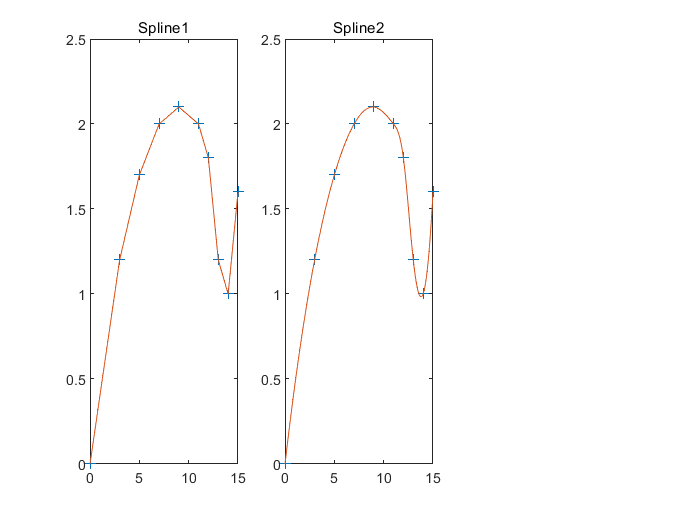

subplot(1,3,1)
plot(x0,y0,'+',x,y1)
title('Spline1')
subplot(1,3,2)
plot(x0,y0,'+',x,y2)
title('Spline2')

dx=diff(x);
dy=diff(y3);
dy_dx=dy./dx;
dy_dx0=dy_dx(1);
ytemp=y3(131:151);
ymin=min(ytemp);
index=find(y3==ymin);
xmin=x(index);
[xmin,ymin]

ans =    13.8000    0.9851
